% Read the data from the CSV file
Tbl = readtable('DataInputFinalv2.csv');


% Display the first lines
disp(Tbl(1:5, :));

    Age    YrsSinceDiagnosis    UDPRSOff    SampleENOffMedAverage    LEDMg_totalDaily_
    ___    _________________    ________    _____________________    _________________

    75             6               10                149                    600       
    75             6               10                133                    600       
    75             6               10                168                    600       
    75             6               10                128                    600       
    79             2               21                102                    250       





% Compute and plot
[R, PValue, H] = corrplot(numericData, 'type', 'Pearson', 'testR', 'on', 'varNames', numericData.Properties.VariableNames);

% Display the correlation matrix and p-values
disp('Correlation Matrix:');

Correlation Matrix:


disp(R);

                               Age       YrsSinceDiagnosis    UDPRSOff    SampleENOffMedAverage    LEDMg_totalDaily_
                             ________    _________________    ________    _____________________    _________________

    Age                             1         -0.13331        0.026023           0.071843              -0.13446     
    YrsSinceDiagnosis        -0.13331                1        -0.28101          -0.066314               0.39641     
    UDPRSOff                 0.026023         -0.28101               1           -0.18723              0.040183     
    SampleENOffMedAverage    0.071843        -0.066314        -0.18723                  1              -0.12905     
    LEDMg_totalDaily_        -0.13446     

disp('P-Values:');

P-Values:


disp(PValue);

                               Age      YrsSinceDiagnosis    UDPRSOff     SampleENOffMedAverage    LEDMg_totalDaily_
                             _______    _________________    _________    _____________________    _________________

    Age                            1          0.21564          0.80981           0.50594                 0.21166    
    YrsSinceDiagnosis        0.21564                1        0.0079998           0.53931              0.00013163    
    UDPRSOff                 0.80981        0.0079998                1          0.080684                 0.71011    
    SampleENOffMedAverage    0.50594          0.53931         0.080684                 1                  0.2308    
    LEDMg_totalDaily_        0.21166      

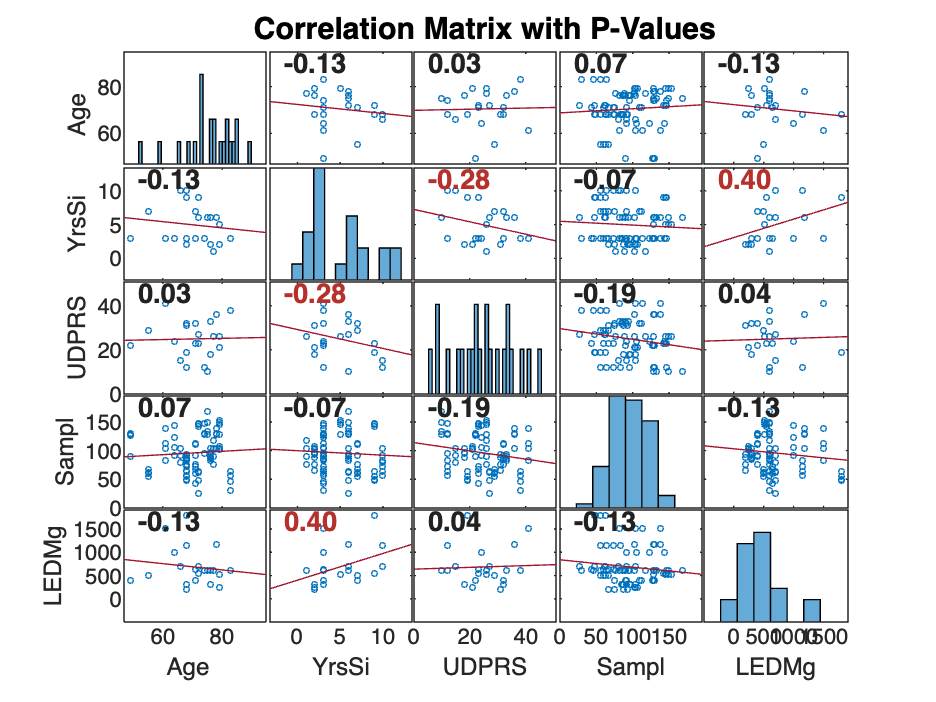


% Use the handles to customize the plot
title('Correlation Matrix with P-Values');

% Customize further
grid on;
colormap('jet');